
a = 1 + mod(109,3);

Problem1

SubProblem1

Part A

a = 1 + mod(109,3); 
t = [0:0.001:1/a]; %time
A1 = a %Amplitude

A1 = 2

f1 =5*a %Frequency

f1 = 10

y1 = inline("a*cos(2*pi*5*a*t)",'a','t');


Part B

a = 1 + mod(109,3);
t = [0:0.001:1/a];
A2 = a/2 %Amplitude

A2 = 1

f2 =6*a %Frequency

f2 = 12

y2 = inline("(a/2)*cos(2*pi*6*a*t)",'a','t');

Part C

a = 1 + mod(109,3);
t = [0:0.001:1/a];
A3 = a/4 %Amplitude

A3 = 0.5000

f3 =10*a %Frequency

f3 = 20

y3 = inline("(a/4)*cos(2*pi*10*a*t)",'a','t');

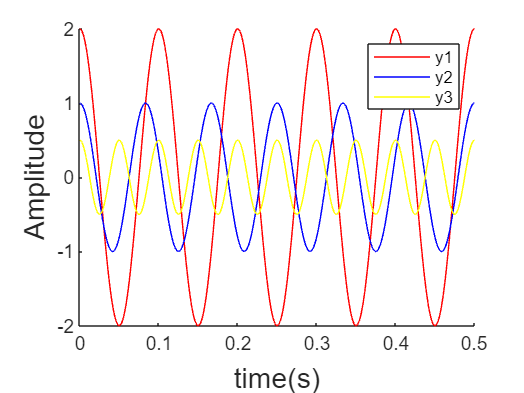

hold on
plot(t,y1(a,t),"r",t,y2(a,t),"b",t,y3(a,t),"y")
xlabel("time(s)","FontSize",15);ylabel("Amplitude","FontSize",15);
legend("y1","y2","y3")
hold off

Problem1

SubProblem2

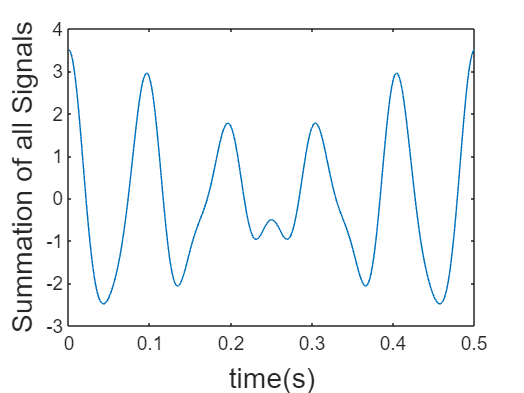

y4 = y1(a,t) + y2(a,t) + y3(a,t); %summation of all three 
plot(t,y4);xlabel("time(s)","FontSize",15);ylabel("Summation of all Signals","FontSize",15);

Problem1

SubProblem3

Part a

F = 14*a;
T = 1/F;
t =[0:T:a];
s1 = y1(a,t)+y2(a,t)+y3(a,t);
subplot(3,1,1)
stem(t*F,s1,'r')
ylabel('Signal(f=14*a)');
xlabel('Samples(n)');
title('Discretization')


Part b

Fn = 20*a; %nyquist frequency
Tn = 1/Fn;
t =[0:Tn:a];
s2 = y1(a,t)+y2(a,t)+y3(a,t);
subplot(3,1,2)
stem(Fn*t,s2,'m')
ylabel('Signal(f=20*a)');
xlabel('Samples(n)');


Part c

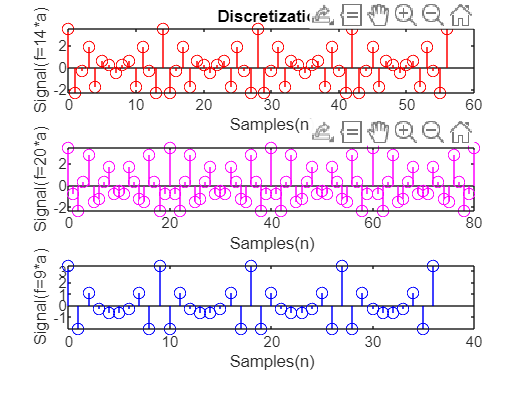

Fa = 9*a; %sampling frequency
Ta = 1/Fa;
t =[0:Ta:a];
s3 = y1(a,t)+y2(a,t)+y3(a,t);
subplot(3,1,3)
stem(Fa*t,s3,'b')
ylabel('Signal(f=9*a)');
xlabel('Samples(n)');

Problem1

SubProblem4

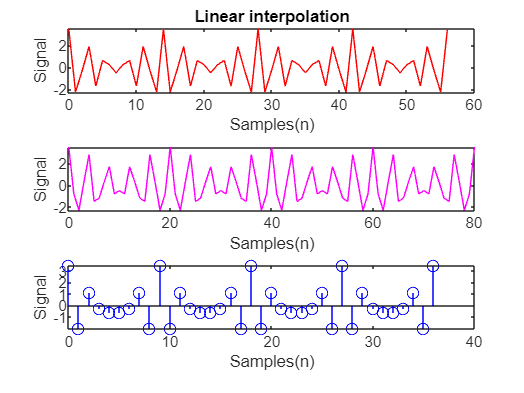

%a
Fs = 14*a;
T = 1/Fs;
t =[0:T:a];
s = y1(a,t)+y2(a,t)+y3(a,t);
subplot(3,1,1)
plot(Fs*t,s,'r')
ylabel('Signal');
xlabel('Samples(n)');
title('Linear interpolation')

%b
Fs = 20*a;
T = 1/Fs;
t =[0:T:a];
s = y1(a,t)+y2(a,t)+y3(a,t);
subplot(3,1,2)
plot(Fs*t,s,'m')
ylabel('Signal');
xlabel('Samples(n)');

%c
Fs = 9*a;
T = 1/Fs;
t =[0:T:a];
s = y1(a,t)+y2(a,t)+y3(a,t);
subplot(3,1,3)
%plot(Fs*t,s,'BusyAction')
ylabel('Signal');
xlabel('Samples(n)');

Problem1

SubProblem5

Part A

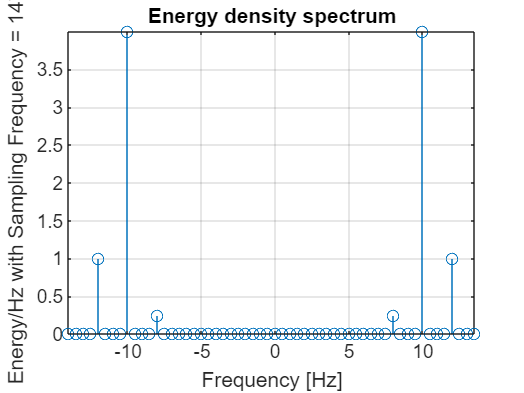

%Part 5:
%a
f = 14*a;
T = 1/f;
t =[0:T:a-T];
s = y1(a,t)+y2(a,t)+y3(a,t);
N=length(s);
y=fft(s,N); 
z=fftshift(y); 
f_vec=[0:1:N-1]*f/N-f/2; 
amplitude_spectra=abs(z)/f; 
amplitude_spectra=abs(z)*T;
figure;stem(f_vec,abs(amplitude_spectra).^2);
xlabel('Frequency [Hz]')
ylabel('Energy/Hz with Sampling Frequency = 14*a')
title('Energy density spectrum')
grid on
set(gcf,'color','w');
axis tight

%calculate total energy
Eg=sum(s.^2)*T 

Eg = 5.2500

Part B

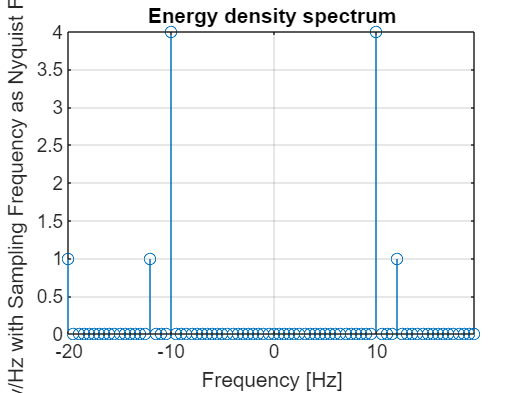

%b
fn = 20*a;
Tn = 1/fn;
t =[0:Tn:a-Tn];
s = y1(a,t)+y2(a,t)+y3(a,t);
N=length(s);
y=fft(s,N); 
z=fftshift(y); 
f_vec=[0:1:N-1]*fn/N-fn/2; 
amplitude_spectra=abs(z)/fn; 
amplitude_spectra=abs(z)*Tn;
figure;stem(f_vec,abs(amplitude_spectra).^2);
xlabel('Frequency [Hz]')
ylabel('Energy/Hz with Sampling Frequency as Nyquist Frequency')
title('Energy density spectrum')
grid on
set(gcf,'color','w');
axis tight

Eg=sum(s.^2)*T 

Eg = 7.8571

Part C

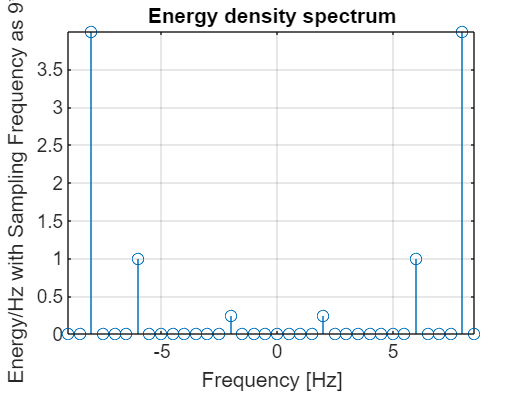

%c
fa = 9*a;
Ta = 1/fa;
t =[0:Ta:a-Ta];
s = y1(a,t)+y2(a,t)+y3(a,t);
N=length(s);
y=fft(s,N); 
z=fftshift(y); 
f_vec=[0:1:N-1]*fa/N-fa/2; 
amplitude_spectra=abs(z)/fa; 
amplitude_spectra=abs(z)*Ta;
figure;stem(f_vec,abs(amplitude_spectra).^2);
xlabel('Frequency [Hz]')
ylabel('Energy/Hz with Sampling Frequency as 9*a')
title('Energy density spectrum')
grid on
set(gcf,'color','w');
axis tight

Eg=sum(s.^2)*T 

Eg = 3.3750

Probelm2

t = linspace(0,10,10000)

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


f1 = sin(2*pi*220*t); %LA
f2 = sin(2*pi*246.94*t); %SI
f3 = sin(2*pi*261.63*t); %DO
f4 = sin(2*pi*293.66 *t); %RA
f5 = sin(2*pi*329.63 *t); %ME
f6 = sin(2*pi*349.23*t); %FA
f7 = sin(2*pi*392.00 *t); %SO
f8 = sin(2*pi*529*t) %DO

f8 =          0   -0.1815    0.3570   -0.5207    0.6670   -0.7912    0.8891   -0.9574    0.9939   -0.9974    0.9678   -0.9059    0.8140   -0.6951    0.5530   -0.3926    0.2191   -0.0383   -0.1437    0.3210   -0.4876    0.6380   -0.7672    0.8709   -0.9456    0.9890   -0.9994    0.9767   -0.9215    0.8357   -0.7221    0.5845   -0.4275    0.2563   -0.0766   -0.1057    0.2844   -0.4538    0.6080   -0.7420    0.8514   -0.9325    0.9825   -1.0000    0.9842   -0.9357    0.8561   -0.7481    0.6152   -0.4619


f9 = [f3 f4 f5 f6 f7 f1 f2 f8]

f9 =          0    0.9973   -0.1460   -0.9760    0.2888    0.9337   -0.4254   -0.8714    0.5530    0.7905   -0.6686   -0.6927    0.7700    0.5800   -0.8549   -0.4549    0.9215    0.3200   -0.9683   -0.1783    0.9944    0.0328   -0.9992    0.1134    0.9826   -0.2572   -0.9449    0.3955    0.8871   -0.5253   -0.8102    0.6439    0.7159   -0.7487   -0.6064    0.8374    0.4838   -0.9082   -0.3509    0.9596    0.2105   -0.9904   -0.0656    1.0000   -0.0808   -0.9881    0.2254    0.9552   -0.3652   -0.9017


Fs = 420 *40

Fs = 16800


audiowrite("Signal.wav",f8,Fs)
%sound(f8,Fs) 
% more the sampling frequecy it plays faster and the pitch gets higher

Problem3

h = "Track00" + a + ".wav"

h = "Track002.wav"

[s,Fs] = audioread(h)

s =     0.1351
    0.1443
    0.1452
    0.1451
    0.1652
    0.1836
    0.1632
    0.1314
    0.1407
    0.1778


Fs = 44100

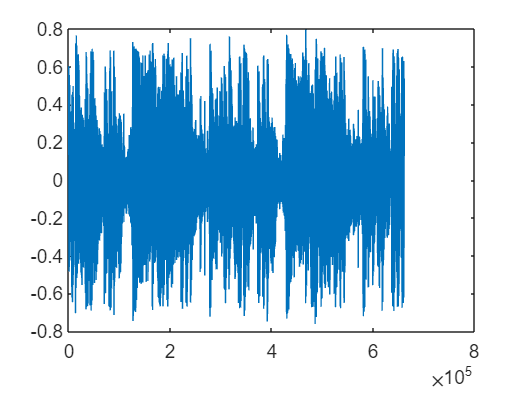

plot(s)

%sound(s,Fs) % original sampling rate

Down Sampling


Fs1 = Fs*0.5 %half the sampling rate

Fs1 = 22050

s1=s(1:2:end);
subplot(3,1,1)
plot(s1n)
ylabel('Signal');
xlabel('Samples');
title("Down Sampling");
%sound(s,Fs1) %half the sampling rate - slowed down a bit
Fs2 = Fs/3 %one-third the sampling rate

Fs2 = 14700

s2 = downsample(s,3);
subplot(3,1,2)
plot(s2)
ylabel('Signal');
xlabel('Samples');
%sound(s,Fs2)  %one third sampling rate - slowed down more

Up Sampling

Fs3 = Fs * 3

Fs3 = 132300

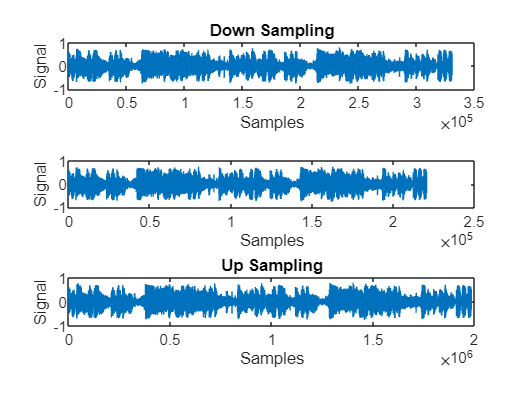

s3 = upsample(s,3);
subplot(3,1,3)
plot(s3)
ylabel('Signal');
xlabel('Samples');
title("Up Sampling");

%sound(s,Fs3) %up sample - way tooooo fast and info lost